# Galerkin's Method for Function Approximation

The norm induced by the $L^2$ function space is the $L^2$-norm


$${\left\|f\right\|}_2 =\sqrt{\int_{\Omega \;} f^2 \;\mathrm{d}\Omega }$$


The $L^2$ inner-product between two functions, $f\left(x\right)\in L^2 ,g\left(x\right)\in L^2 ,x\in \mathbb{R}$, is


$${\left\langle f,g\right\rangle }_{L^2 } =\int_{\Omega \;} f\left(x\right)\;g\left(x\right)\;\mathrm{d}\Omega$$


Polynomial functions are in $L^2$ so we can use change of basis with the $L^2$ inner product.

Consider the cubic basis for the monomials:

degree = 3;
variate = sym("x");
domain = [0 1];
M = PolynomialBasisFunction( "Monomial", degree, variate, domain )

$$M = \left[\begin{array}{c} 1\\ x\\ x^{2}\\ x^{3} \end{array}\right]$$

We often write polynomials in a form similar to: 


$$f\left(x\right)=5x^3 -2x^2 +x$$


But we could equivalently write this in a "basis" form:


$$f\left(x\right)=\sum_{i=0}^p {\mathbf{m}}_{\mathrm{i}} {\mathbf{M}}_i ={\mathbf{m}}_0 {\mathbf{M}}_0 +{\mathbf{m}}_1 {\mathbf{M}}_1 +{\mathbf{m}}_2 {\mathbf{M}}_2 +{\mathbf{m}}_3 {\mathbf{M}}_3 \longrightarrow \;\left\lbrack \begin{array}{cccc}
0 & 1 & -2 & 5
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x^0 \\
x^1 \\
x^2 \\
x^3 
\end{array}\right\rbrack$$


Similarly we can define a polynomial in a different basis, such as the Legendre basis:


$$f\left(x\right)=\sum_{i=0}^p {\mathbf{p}}_{\mathrm{i}} {\mathbf{P}}_i ={\mathbf{p}}_0 {\mathbf{P}}_0 +{\mathbf{p}}_1 {\mathbf{P}}_1 +{\mathbf{p}}_2 {\mathbf{P}}_2 +{\mathbf{p}}_3 {\mathbf{P}}_3 \longrightarrow \;\left\lbrack \begin{array}{cccc}
{\mathbf{p}}_0  & {\mathbf{p}}_1  & {\mathbf{p}}_2  & {\mathbf{p}}_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x^0 \\
x^1 \\
\frac{3x^2 -1}{2}\\
\frac{5x^3 -3x}{2}
\end{array}\right\rbrack$$


Note that we can use the exact same change of basis idea to determine the coefficients $\mathbf{p}$:


$$\left\lbrack \begin{array}{ccc}
\langle \;{\mathbf{P}}_0 ,{\mathbf{P}}_0 \rangle_{L^2 }  & \cdots \;\; & \langle \;{\mathbf{P}}_1 ,{\mathbf{P}}_n \rangle_{L^2 } \\
\vdots \; & \ddots  & \vdots \;\\
\langle \;{\mathbf{P}}_n ,{\mathbf{P}}_1 \rangle_{L^2 }  & \cdots  & \langle \;{\mathbf{P}}_n ,{\mathbf{P}}_n \rangle_{L^2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathbf{p}}_1 \\
\vdots \;\\
{\mathbf{p}}_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\langle \;{\mathbf{P}}_1 ,{\mathbf{M}}_1 \rangle_{L^2 }  & \cdots \;\; & \langle \;{\mathbf{P}}_1 ,{\mathbf{M}}_n \rangle_{L^2 } \\
\vdots \; & \ddots  & \vdots \;\\
\langle \;{\mathbf{P}}_n ,{\mathbf{M}}_1 \rangle_{L^2 }  & \cdots  & \langle \;{\mathbf{P}}_n ,{\mathbf{M}}_n \rangle_{L^2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathbf{m}}_1 \\
\vdots \;\\
{\mathbf{m}}_n 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{cccc}
\langle \;{\mathbf{P}}_0 ,{\mathbf{P}}_0 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_0 ,{\mathbf{P}}_1 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_0 ,{\mathbf{P}}_2 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_0 ,{\mathbf{P}}_3 \rangle_{L^2 } \\
\langle \;{\mathbf{P}}_1 ,{\mathbf{P}}_0 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_1 ,{\mathbf{P}}_1 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_1 ,{\mathbf{P}}_2 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_1 ,{\mathbf{P}}_3 \rangle_{L^2 } \\
\langle \;{\mathbf{P}}_2 ,{\mathbf{P}}_0 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_2 ,{\mathbf{P}}_1 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_2 ,{\mathbf{P}}_2 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_2 ,{\mathbf{P}}_3 \rangle_{L^2 } \\
\langle \;{\mathbf{P}}_3 ,{\mathbf{P}}_0 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_3 ,{\mathbf{P}}_1 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_3 ,{\mathbf{P}}_2 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_3 ,{\mathbf{P}}_3 \rangle_{L^2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathbf{p}}_0 \\
{\mathbf{p}}_1 \\
{\mathbf{p}}_2 \\
{\mathbf{p}}_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\langle \;{\mathbf{P}}_0 ,{\mathbf{M}}_0 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_0 ,{\mathbf{M}}_1 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_0 ,{\mathbf{M}}_2 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_0 ,{\mathbf{M}}_3 \rangle_{L^2 } \\
\langle \;{\mathbf{P}}_1 ,{\mathbf{M}}_0 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_1 ,{\mathbf{M}}_1 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_1 ,{\mathbf{M}}_2 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_1 ,{\mathbf{M}}_3 \rangle_{L^2 } \\
\langle \;{\mathbf{P}}_2 ,{\mathbf{M}}_0 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_2 ,{\mathbf{M}}_1 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_2 ,{\mathbf{M}}_2 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_2 ,{\mathbf{M}}_3 \rangle_{L^2 } \\
\langle \;{\mathbf{P}}_3 ,{\mathbf{M}}_0 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_3 ,{\mathbf{M}}_1 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_3 ,{\mathbf{M}}_2 \rangle_{L^2 }  & \langle \;{\mathbf{P}}_3 ,{\mathbf{M}}_3 \rangle_{L^2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathbf{m}}_0 \\
{\mathbf{m}}_1 \\
{\mathbf{m}}_2 \\
{\mathbf{m}}_3 
\end{array}\right\rbrack$$


For some simplicity note that if we have two vectors of basis polynomials and wish to create these matrices quickly using Matlab's built-in vectorization, the Matlab command: `P .* transpose( M )` will accomplish this (look at the indexing). Note that while I've used zero-based indexing in the equations, Matlab is one-indexed.

A = sym( "A", [4,1] )

$$A = \left[\begin{array}{c} A_{1}\\ A_{2}\\ A_{3}\\ A_{4} \end{array}\right]$$

B = sym( "B", [4,1] )

$$B = \left[\begin{array}{c} B_{1}\\ B_{2}\\ B_{3}\\ B_{4} \end{array}\right]$$

A .* transpose( B )

$$ans = \left[\begin{array}{cccc} A_{1}\,B_{1} & A_{1}\,B_{2} & A_{1}\,B_{3} & A_{1}\,B_{4}\\ A_{2}\,B_{1} & A_{2}\,B_{2} & A_{2}\,B_{3} & A_{2}\,B_{4}\\ A_{3}\,B_{1} & A_{3}\,B_{2} & A_{3}\,B_{3} & A_{3}\,B_{4}\\ A_{4}\,B_{1} & A_{4}\,B_{2} & A_{4}\,B_{3} & A_{4}\,B_{4} \end{array}\right]$$

And then we can symbolically integrate element-wise by simply wrapping the statement in `int( <statement> ).  `

`(The Hold=true just keeps in indefinite form for your reading pleasure).`

int( A .* transpose( B ), variate, Hold=true )

$$ans = \left[\begin{array}{cccc} \int A_{1}\,B_{1}\mathrm{d}x & \int A_{1}\,B_{2}\mathrm{d}x & \int A_{1}\,B_{3}\mathrm{d}x & \int A_{1}\,B_{4}\mathrm{d}x\\ \int A_{2}\,B_{1}\mathrm{d}x & \int A_{2}\,B_{2}\mathrm{d}x & \int A_{2}\,B_{3}\mathrm{d}x & \int A_{2}\,B_{4}\mathrm{d}x\\ \int A_{3}\,B_{1}\mathrm{d}x & \int A_{3}\,B_{2}\mathrm{d}x & \int A_{3}\,B_{3}\mathrm{d}x & \int A_{3}\,B_{4}\mathrm{d}x\\ \int A_{4}\,B_{1}\mathrm{d}x & \int A_{4}\,B_{2}\mathrm{d}x & \int A_{4}\,B_{3}\mathrm{d}x & \int A_{4}\,B_{4}\mathrm{d}x \end{array}\right]$$

We now proceed with our calculations.

the definition of Galerkin's Method:

Let $V$ be an infinite-dimensional Hilbert space, and $\tilde{\;V}$ be a finite dimenstional subspace, i.e., $\tilde{V} \subset V$.  Let $f$ be some integrable function, i.e., $f\in L_2$.  Find $\tilde{u} \in \tilde{V}$ such that


$$\left\langle \delta \tilde{u} ,\tilde{u} -f\right\rangle =0,$$
    
$$\forall \delta \tilde{u} \in \tilde{V}$$
  

We can utilize the __ property of inner products to rewrite this as


$$\left\langle \delta \tilde{u} ,\tilde{u} \right\rangle -\left\langle \delta \tilde{u} ,f\right\rangle =0$$



$$\left\langle \delta \tilde{u} ,\tilde{u} \right\rangle =\left\langle \delta \tilde{u} ,f\right\rangle$$


Recognizing that $\tilde{V}$ is a vector space, specifically the polynomial space, let:


$$\delta \tilde{u} =\sum_{i=0}^p {\mathbf{c}}_i {\mathbf{C}}_i$$



$$\tilde{u} =\sum_{j=0}^q {\mathbf{d}}_j {\mathbf{D}}_j$$


Meaning we can rewrite the previous result as


$$\left\langle \sum_{i=0}^p {\mathbf{c}}_i {\mathbf{C}}_i ,\sum_{j=0}^q {\mathbf{d}}_j {\mathbf{D}}_j \right\rangle =\left\langle \sum_{i=0}^p {\mathbf{c}}_i {\mathbf{C}}_i ,f\right\rangle$$


And then perform some manipulations:


$$\sum_{i=0}^p {\mathbf{c}}_i \left\langle {\mathbf{C}}_i ,\sum_{j=0}^q {\mathbf{d}}_j {\mathbf{D}}_j \right\rangle =\sum_{i=0}^p {\mathbf{c}}_i \;\left\langle {\mathbf{C}}_i ,f\right\rangle$$



$$\left\langle {\mathbf{C}}_i ,\sum_{j=0}^q {\mathbf{d}}_j {\mathbf{D}}_j \right\rangle =\;\left\langle {\mathbf{C}}_i ,f\right\rangle$$



$$\sum_{i=0,\;j=0}^{p,q} {\mathbf{d}}_j \left\langle {\mathbf{C}}_i ,{\mathbf{D}}_j \right\rangle =\;\left\langle {\mathbf{C}}_i ,f\right\rangle$$


Now, if we choose our bases, $\mathbf{C}$ and $\mathbf{D}$, such that the are bases for the same space i.e., $\mathbf{C}\in \tilde{V}$and $\mathbf{D}\in \tilde{V}$ (an approach known as the *Bubnov-Galerkin method*) we then have $\mathbf{C}\equiv \mathbf{D}$ through change of basis.  Then we have:


$$\sum_{i=0,j=0}^q {\mathbf{d}}_j \left\langle {\mathbf{C}}_i ,{\mathbf{C}}_j \right\rangle =\;\left\langle {\mathbf{C}}_i ,f\right\rangle$$


Or, written in matrix form:


$$\left\lbrack \begin{array}{ccc}
\left\langle C_1 ,C_1 \right\rangle  & \cdots  & \left\langle C_1 ,C_q \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle C_q ,C_1 \right\rangle  & \cdots  & \left\langle C_q ,C_q \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
\vdots \\
d_q 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left\langle C_1 ,f\right\rangle \\
\vdots \\
\left\langle C_q ,f\right\rangle 
\end{array}\right\rbrack$$


So there is an *exact* solution to this Poisson equation, $u\left(x\right)$, that we've decided we will approximate as a polynomial function i.e., in a polynomial basis.  Let's denote the polynomial basis as $\Phi \left(x\right)$.  Putting this into our governing equation we have:

Let's suppose that we have some function that we wish to approximate as a polynomial. Specifically, we want to find the polynomial function that most closely represents the function over a finite domain, in the $L^2$ sense.  

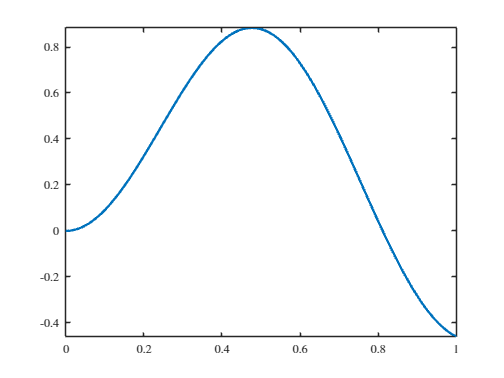

clear
close all

x = sym("x");
domain = [0 1];
f(x) = sin( pi * x ) ^ 2 + cos( x ) - 1;

figure
fplot( f, domain, LineWidth=2 )

Let's suppose that we wish to approximate this function with a quadratic polynomial.

degree = 2;
poly_basis = PolynomialBasisFunction( "Monomial", degree, x, domain )

$$poly\_basis = \left[\begin{array}{c} 1\\ x\\ x^{2} \end{array}\right]$$

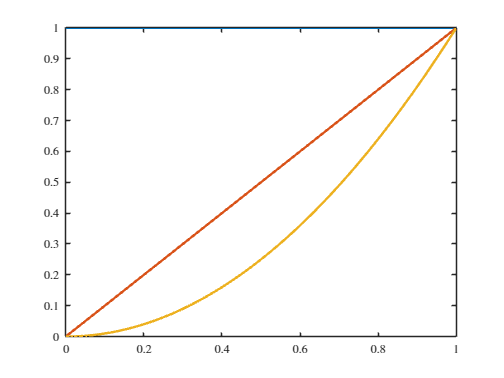


figure
fplot( poly_basis, domain, LineWidth=2 )

We can assemble the Gram matrix as discussed previously, in a single line of code:

M = int( poly_basis .* transpose( poly_basis ), domain )

$$M = \left[\begin{array}{ccc} 1 & \frac{1}{2} & \frac{1}{3}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} \end{array}\right]$$

And the force vector similarly compactly:

F = int( poly_basis * f, domain )

$$F = \left[\begin{array}{c} \sin\left(1\right)-\frac{1}{2}\\ \cos\left(1\right)+\sin\left(1\right)-\frac{5}{4}\\ 2\,\cos\left(1\right)-\sin\left(1\right)-\frac{1}{4\,\pi^{2}}-\frac{1}{6} \end{array}\right]$$

And the coefficients of the polynomial are then found by solving the linear system of equations


$$M\;d=F$$


d = M \ F

$$d = \left[\begin{array}{c} \frac{48\,\pi^{2}\,\cos\left(1\right)-114\,\pi^{2}\,\sin\left(1\right)+71\,\pi^{2}-15}{2\,\pi^{2}}\\ -\frac{3\,\left(56\,\pi^{2}\,\cos\left(1\right)-112\,\pi^{2}\,\sin\left(1\right)+64\,\pi^{2}-15\right)}{\pi^{2}}\\ \frac{15\,\left(12\,\pi^{2}\,\cos\left(1\right)-22\,\pi^{2}\,\sin\left(1\right)+12\,\pi^{2}-3\right)}{\pi^{2}} \end{array}\right]$$

We then multiply our polynomial basis by these coefficients to recover the solution -- the cubic polynomial function that best approximates the function over the domain:

poly = transpose( d ) * poly_basis

$$poly = \frac{15\,\left(12\,\pi^{2}\,\cos\left(1\right)-22\,\pi^{2}\,\sin\left(1\right)+12\,\pi^{2}-3\right)\,x^{2}}{\pi^{2}}-\frac{3\,\left(56\,\pi^{2}\,\cos\left(1\right)-112\,\pi^{2}\,\sin\left(1\right)+64\,\pi^{2}-15\right)\,x}{\pi^{2}}+\frac{48\,\pi^{2}\,\cos\left(1\right)-114\,\pi^{2}\,\sin\left(1\right)+71\,\pi^{2}-15}{2\,\pi^{2}}$$

poly = expand( poly )

$$poly = 24\,\cos\left(1\right)-192\,x-57\,\sin\left(1\right)-168\,x\,\cos\left(1\right)+336\,x\,\sin\left(1\right)+\frac{45\,x}{\pi^{2}}+180\,x^{2}\,\cos\left(1\right)-330\,x^{2}\,\sin\left(1\right)-\frac{15}{2\,\pi^{2}}+180\,x^{2}-\frac{45\,x^{2}}{\pi^{2}}+\frac{71}{2}$$

Error

l2_error = ComputeL2Error( f, poly, domain );
l2_error = vpa( l2_error )

$$l2\_error = 0.097690210474410436883990070713311$$

Plotting

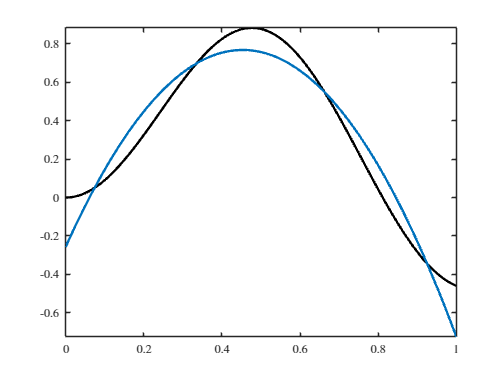

figure
hold on
fplot( f, domain, LineWidth=2, Color="k" )
fplot( poly, domain, LineWidth=2, SeriesIndex=1 )

Now, that doesn't appear to be a particularly good fit, but let's look at what happens if we use a higher-order polynomial function in our approximation.  But first, let's collect our work above to write a few simple functions that perform the scalar projection:

Now, you might just look at that code and thought it's nothing special, but I think it's absolutely beautiful that we were able to implement scalar projection in less than two-dozen lines of code.  And if you take away some of the extra fluff that I've done out of personal preference, we could have written it even more compactly:

So now lets see what happens if we use a high-order polynomial for our approximation -- this time a quartic polynomial

degree = 4;

[u, M, F, N, d] = ScalarProjection( "Monomial", f, degree, domain );
l2_error = ComputeL2Error( f, u, domain );
l2_error = vpa( l2_error )

$$l2\_error = 0.0091791816154028232242357082612294$$

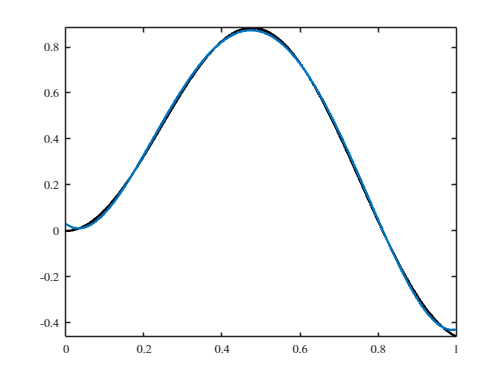


figure
hold on
fplot( f, domain, LineWidth=2, Color="k" )
fplot( u, domain, LineWidth=2, SeriesIndex=1 )

As we can clearly see, the higher-order polynomial is a much better approximation of the function.  We can perform a "degree-refinement study" to explore and quantify the improvement of approximation as we increase the polynomial degree of the approximation.

## Degree Refinement Study

degree = (0:12);
l2_error = zeros( size( degree ) );
for p = 1 : length( degree )
    u = ScalarProjection( "Monomial", f, degree(p), domain );
    l2_error(p) = double( vpa( ComputeL2Error( f, u, domain ), 24 ) );
    disp( "Degree: " + num2str( degree(p) ) + ", L2 Error: " + num2str( l2_error(p) ) )
end

Degree: 0, L2 Error: 0.40758
Degree: 1, L2 Error: 0.38458
Degree: 2, L2 Error: 0.09769
Degree: 3, L2 Error: 0.097679
Degree: 4, L2 Error: 0.0091792
Degree: 5, L2 Error: 0.0091792
Degree: 6, L2 Error: 0.00043655
Degree: 7, L2 Error: 0.00043655
Degree: 8, L2 Error: 1.2571e-05
Degree: 9, L2 Error: 1.2571e-05
Degree: 10, L2 Error: 2.4319e-07
Degree: 11, L2 Error: 2.4319e-07
Degree: 12, L2 Error: 6.644e-09


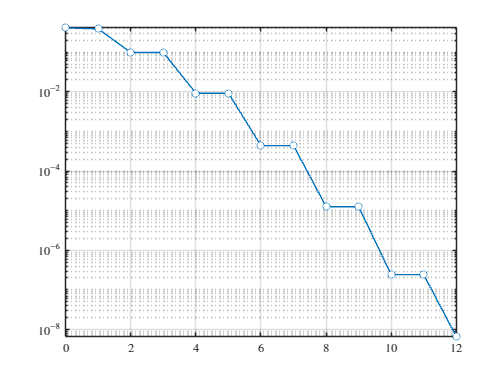


figure
plot( degree, l2_error, Marker="o", MarkerFaceColor="auto" )
ax = gca;
ax.YScale = "log";
ax.XGrid = "on";
ax.YGrid = "on";

## Effect of different polynomial bases

So what's the point of all these different polynomial bases?

[~, M, ~, ~, ~] = ScalarProjection( "Monomial", f, 7, domain )

$$M = \left[\begin{array}{cccccccc} 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8} & \frac{1}{9}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8} & \frac{1}{9} & \frac{1}{10}\\ \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8} & \frac{1}{9} & \frac{1}{10} & \frac{1}{11}\\ \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8} & \frac{1}{9} & \frac{1}{10} & \frac{1}{11} & \frac{1}{12}\\ \frac{1}{6} & \frac{1}{7} & \frac{1}{8} & \frac{1}{9} & \frac{1}{10} & \frac{1}{11} & \frac{1}{12} & \frac{1}{13}\\ \frac{1}{7} & \frac{1}{8} & \frac{1}{9} & \frac{1}{10} & \frac{1}{11} & \frac{1}{12} & \frac{1}{13} & \frac{1}{14}\\ \frac{1}{8} & \frac{1}{9} & \frac{1}{10} & \frac{1}{11} & \frac{1}{12} & \frac{1}{13} & \frac{1}{14} & \frac{1}{15} \end{array}\right]$$

vpa( cond( M ) )

$$ans = 15257575741.646942839088274073455$$

[~, M, ~, ~, ~] = ScalarProjection( "Legendre", f, 7, domain )

$$M = \left[\begin{array}{cccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{1}{3} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{1}{5} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{1}{7} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{1}{9} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{1}{11} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{13} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{15} \end{array}\right]$$

vpa( cond( M ) )

$$ans = 15.0$$

Conditioning

[u, M, F, N, d] = ScalarProjection( "Monomial", f, 7, domain );
d_double = pcg( double( M ), double( F ) );

pcg stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 1.4e-06.


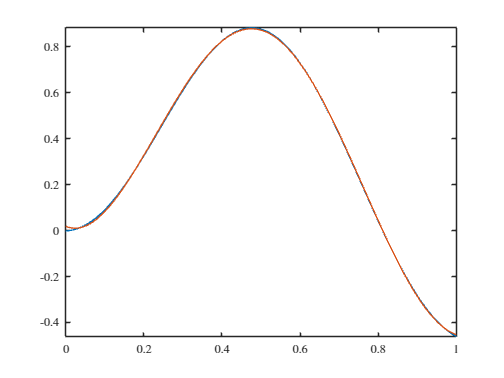

u_double = transpose( d_double ) * N;
figure
hold on
fplot( u, domain )
fplot( u_double, domain )


[u, M, F, N, d] = ScalarProjection( "Legendre", f, 7, domain );
d_double = pcg( double( M ), double( F ) );

pcg converged at iteration 6 to a solution with relative residual 1.6e-08.


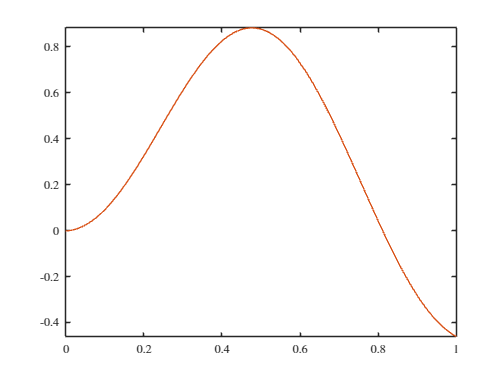

u_double = transpose( d_double ) * N;
figure
hold on
fplot( u, domain )
fplot( u_double, domain )

degree = (0:12);
poly_bases = ["Bernstein", "Chebyshev", "Lagrange", "Legendre", "Monomial"];
cond_vals = zeros( length( degree ), length( poly_bases ) );
for p = 1 : length( degree )
    for n = 1 : length( poly_bases )
        [~, M, ~, ~, ~] = ScalarProjection( poly_bases(n), f, degree(p), domain );
        cond_vals(p, n) = double( cond( vpa( M, 24 ) ) );
        disp( "Degree: " + num2str( degree(p) ) + ", Basis: " + poly_bases(n) + ", Cond = " + num2str( cond_vals(p, n) ) )
    end
end

Degree: 0, Basis: Bernstein, Cond = 1
Degree: 0, Basis: Chebyshev, Cond = 1
Degree: 0, Basis: Lagrange, Cond = 1
Degree: 0, Basis: Legendre, Cond = 1
Degree: 0, Basis: Monomial, Cond = 1
Degree: 1, Basis: Bernstein, Cond = 3
Degree: 1, Basis: Chebyshev, Cond = 3
Degree: 1, Basis: Lagrange, Cond = 3
Degree: 1, Basis: Legendre, Cond = 3
Degree: 1, Basis: Monomial, Cond = 19.2815
Degree: 2, Basis: Bernstein, Cond = 10
Degree: 2, Basis: Chebyshev, Cond = 3.7859
Degree: 2, Basis: Lagrange, Cond = 6.8796
Degree: 2, Basis: Legendre, Cond = 5
Degree: 2, Basis: Monomial, Cond = 524.0568
Degree: 3, Basis: Bernstein, Cond = 35
Degree: 3, Basis: Chebyshev, Cond = 5.9345
Degree: 3, Basis: Lagrange, Cond = 9.361
Degree: 3, Basis: Legendre, Cond = 7
Degree: 3, Basis: Monomial, Cond = 15513.7387
Degree: 4, Basis: Bernstein, Cond = 126
Degree: 4, Basis: Chebyshev, Cond = 6.2427
Degree: 4, Basis: Lagrange, Cond = 14.1391
Degree: 4, Basis: Legendre, Cond = 9
Degree: 4, Basis: Monomial, Cond = 476607.2502

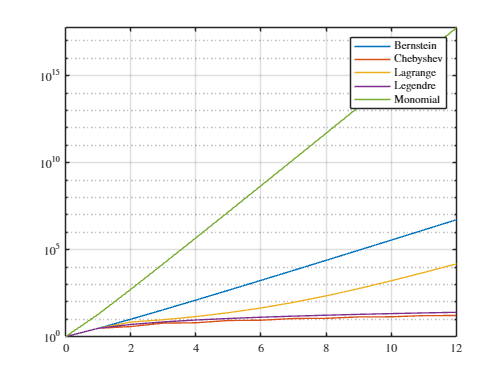


figure
plot( degree, cond_vals )
legend( poly_bases )
ax = gca;
ax.YScale = "log";
ax.XGrid = "on";
ax.YGrid = "on";

clear
x = sym("x");
domain = [-0.1 0.1];
f(x) = real( x^x )

$$f(x) = \mathrm{real}\left(x^{x}\right)$$

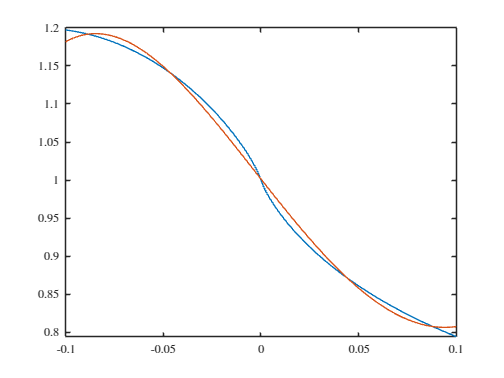


degree = 4;
[u, M, F, N, d] = ScalarProjection( "Legendre", f, degree, domain );
% l2_error = ComputeL2Error( f, u, domain );
% l2_error = vpa( l2_error )

figure
hold on
fplot( f, domain )
fplot( u, domain )